# Frequency effect on Steered Plane wave with a Linear Array

[PFIELD RMS acoustic pressure field of a linear or convex array (biomecardio.com)](https://www.biomecardio.com/MUST/functions/html/pfield_doc.html#85)

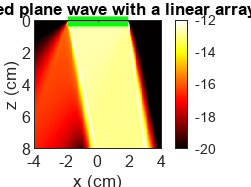

% In all working documents it is good practice to use "clear; clear all;
% clc;" to clear the workspace, commamnd workspace, command window. 
% Aka will clear everything that could cause problems from previously saved
% varibles, functions, etc.
clear; clear all; clc;

param = getparam('L11-5v');
% Steered plane wave with linear array WITHOUT attenuation 
    tilt = 10/180*pi;               % tilt angle in rad
    txdel = txdelay(param,tilt);    % in s
    x = linspace(-4e-2,4e-2,150);   % in m
    z = linspace(0,8e-2,150);       % in m
    [x,z] = meshgrid(x,z);
    P = pfield(x,z,txdel,param);
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0])                  % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')

    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off

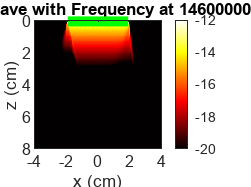



% for loop for different Frequencies on an attenuated linear array
for fc = 0.6e6:1e6:14.6e6
    param = setfield(param,'fc',fc);    % reaches into the get param structure and changes the parameter 'fc' (frequency)
    param.attenuation = 0.5;            % attenuation coefficient (in dB/cm/MHz)
    P = pfield(x,z,txdel,param);
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
        caxis([-20 0])                  % dynamic range = [-20,0] dB
        c = colorbar;
        c.YTickLabel{end} = '0 dB';
        colormap hot
        axis equal ij tight
        xlabel('x (cm)'), ylabel('z (cm)')
        title(['A plane wave with Frequency at ' num2str(fc) 'Hz'])
        hold on
        plot(xe*1e2,ze*1e2,'g','Linewidth',5)
        hold off

    saveas(gcf,['change frequency' num2str(fc) '.jpg'])
end 